#### Name : Ghosh Kushanava Amitava

#### Roll No : 220123083

#### Course : MA 423

format long e

Q.1  Write a function **mychol()** that recursively computes the **Cholesky factor of an n x n** **Positive Definite Matrix** using **Outer Product Formulation**

a = input("Enter the value of a: ")

a =      8


b = input("Enter the value of b: ")

b =      4


n = input("Enter the value of n: ")

n =      3


r = a + (b - a).*rand(n, 1);
D = diag(r);
B = randn(n);
[Q, R] = qr(B);
A = Q.'*D*Q

A =      5.060518181666655e+00    -3.625664289001362e-01     6.976134168963066e-02
    -3.625664289001362e-01     6.720695126995171e+00    -3.240961499059264e-01
     6.976134168963077e-02    -3.240961499059262e-01     5.031713322499816e+00


G = mychol(A)

G =      2.249559552816208e+00    -1.611721852156534e-01     3.101111130945475e-02
                         0     2.587415438948292e+00    -1.233269371925521e-01
                         0                         0     2.239540600220919e+00


G_cap = chol(A)

G_cap =      2.249559552816208e+00    -1.611721852156534e-01     3.101111130945475e-02
                         0     2.587415438948292e+00    -1.233269371925521e-01
                         0                         0     2.239540600220919e+00


norm(G - G_cap)

ans =      2.797157557069881e-17


Q.2  To note the **extreme ill-conditioning** of the **Hilbert Matrix**

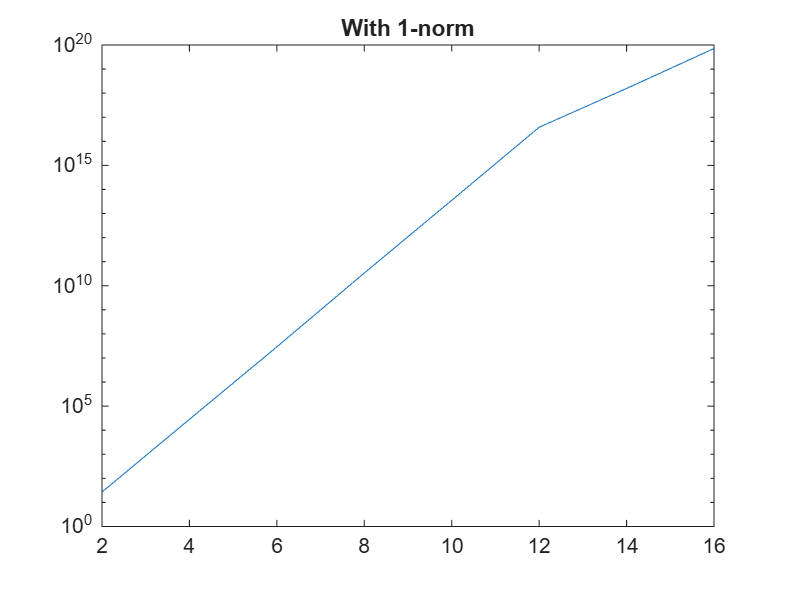

C1 = [];
C2 = [];
Cinf = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C1 = [C1; cond(H, 1)];
    C2 = [C2; cond(H, 2)];
    Cinf = [Cinf, cond(H, inf)];
end
semilogy(N, C1)
title('With 1-norm');

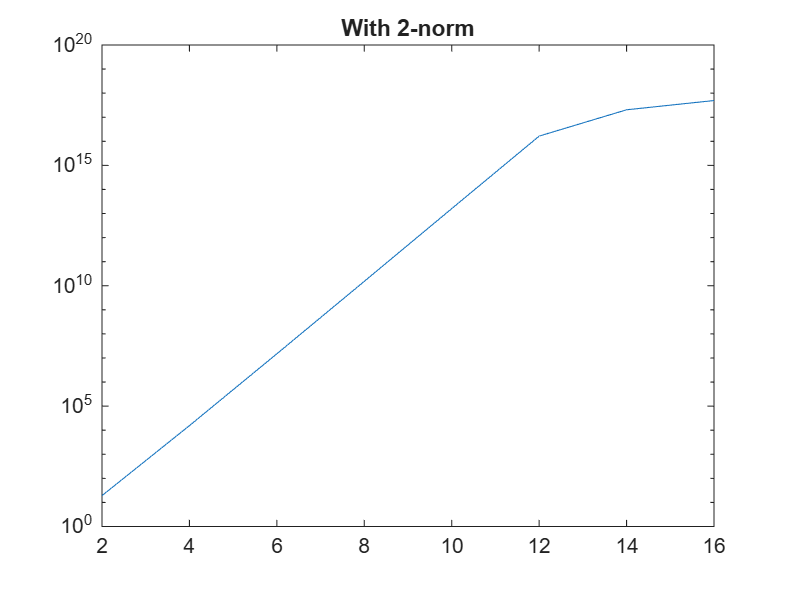

semilogy(N, C2);
title('With 2-norm');

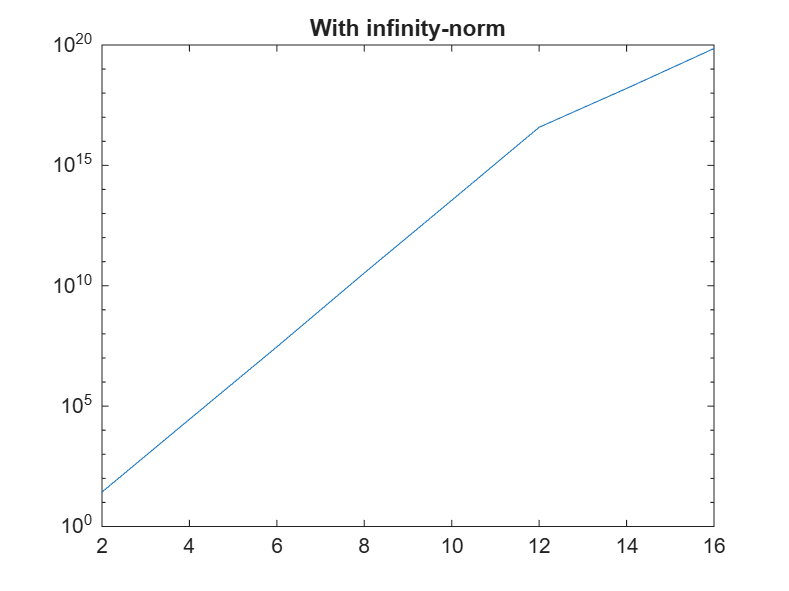

semilogy(N, Cinf)
title('With infinity-norm');

Q.3  Finding Solutions of **Hx = b** via different methods where H = Hilbert matrix

N = 8:10;
for n = N
    H = hilb(n);
    HI = invhilb(n);
    x = rand(n, 1);
    b = H*x;
    x1 = H\b;
    x2 = HI*b;
    x3 = geppsolve(H, b);
    fprintf("For n = %d", n);
    [x x1 x2 x3]
    [cond(H) norm(x-x1)/norm(x) norm(x-x2)/norm(x) norm(x-x3)/norm(x)]
end

For n = 8

ans =      3.922270195341682e-01     3.922270195242107e-01     3.922270195253077e-01     3.922270195242107e-01
     6.554778901775566e-01     6.554778906978911e-01     6.554778898134828e-01     6.554778906978911e-01
     1.711866878115618e-01     1.711866811307872e-01     1.711866799741983e-01     1.711866811307872e-01
     7.060460880196088e-01     7.060461237450252e-01     7.060461491346359e-01     7.060461237450252e-01
     3.183284637742068e-02     3.183275104069676e-02     3.183272480964661e-02     3.183275104069676e-02
     2.769229849608900e-01     2.769231189522584e-01     2.769233286380768e-01     2.769231189522584e-01
     4.617139063115394e-02     4.617129577940496e-02     4.617133736610413e-02     4.617129577940496e-02
     9.713178123584754e-02     9.713180788433257e-02     9.713182598352432e-02     9.713180788433257e-02


ans =      1.525757557941221e+10     1.780754902757503e-07     3.433441110761526e-07     1.780754902757503e-07


For n = 9

ans =      8.234578283272926e-01     8.234578281580103e-01     8.234578281699214e-01     8.234578281580103e-01
     6.948286229758170e-01     6.948286347683016e-01     6.948286416009068e-01     6.948286347683016e-01
     3.170994800608605e-01     3.170992792499711e-01     3.170992732048035e-01     3.170992792499711e-01
     9.502220488383549e-01     9.502234884029427e-01     9.502232074737549e-01     9.502234884029427e-01
     3.444608050290876e-02     3.444078415185154e-02     3.443813323974609e-02     3.444078415185154e-02
     4.387443596563982e-01     4.387551987976586e-01     4.387540817260742e-01     4.387551987976586e-01
     3.815584570930084e-01     3.815459865396040e-01     3.815507888793945e-01     3.815459865396040e-01
     7.655167881490024e-01     7.655243313155156e-01     7.655258178710938e-01     7.655243313155156e-01
     7.951999011370632e-01     7.951980352331178e-01     7.951993942260742e-01     7.951980352331178e-01


ans =      4.931534423763629e+11     9.883108841661868e-06     8.972759527091016e-06     9.883108841661868e-06


For n = 10

ans =      1.868726045543786e-01     1.868726049016805e-01     1.868726040702313e-01     1.868726049016805e-01
     4.897643957882311e-01     4.897643668657156e-01     4.897643737494946e-01     4.897643668657156e-01
     4.455862007108995e-01     4.455867988291982e-01     4.455864429473877e-01     4.455867988291982e-01
     6.463130101112646e-01     6.463077037365202e-01     6.463232040405273e-01     6.463077037365202e-01
     7.093648308580726e-01     7.093896245101668e-01     7.093124389648438e-01     7.093896245101668e-01
     7.546866819823609e-01     7.546197211071410e-01     7.546539306640625e-01     7.546197211071410e-01
     2.760250769985784e-01     2.761332596647637e-01     2.760467529296875e-01     2.761332596647637e-01
     6.797026768536748e-01     6.795995368087093e-01     6.796722412109375e-01     6.795995368087093e-01
     6.550980039738407e-01     6.551515056182776e-01     6.550140380859375e-01     6.551515056182776e-01
     1.626117351946306e-01     1.626000948165327e

ans =      1.602494102542768e+13     1.014940871877233e-04     6.477530710956861e-05     1.014940871877233e-04


(A)  10 digits are lost in computing x1, 11 digits are lost in computing x2, 13 digits are lost in computing x3.

(B)  Yes, the loss of accuracy in each case agree with the value predicted by **Rule of Thumb** mentioned earlier.

(C)  There isn't much difference for each n. Moreover, the error is of nearly the same order.

Q.4  To illustrate that a small value of the norm of the residual alone is not enough to guarantee an accurate answer

n = 10;
H = hilb(n);
x = randn(n, 1);
b = H*x;
x1 = H\b;
r = H*x1-b;
disp([norm(r)/norm(b) norm(x-x1)/norm(x)])

     7.536298957290407e-17     2.793648300801826e-05



Conclusion : 

1.  A small residual norm **does not necessarily imply** that the computed solution is close to the true solution.

2.  For ill-conditioned matrices like the **Hilbert matrix**, the solution can be very inaccurate even if the residual is tiny.

Q.5  Show that only the coefficient matrix A having a small condition number is not enough to ensure accuracy in the computed solution of system Ax = b.

N = 32:32:64;
for n = N
    W = Wilkinson(n);
    x = rand(n, 1);
    b = W*x;
    x1 = geppsolve(W, b);
    r = W*x1-b;
    fprintf("For n = %d", n);
    disp("Using GEPP");
    disp([norm(x - x1)/norm(x) cond(W, inf) norm(r)/norm(b)])

    [Q, R] = qr(W);
    y = Q'*b;
    x_qr = colbackward(R, y);
    r_qr = W*x_qr-b;
    disp("Using QR decomposition");
    disp([norm(x - x_qr)/norm(x) cond(W, inf) norm(r_qr)/norm(b)])
end

For n = 32

Using GEPP


     2.930896093537351e-09     3.200000000000000e+01     4.619793397943289e-10



Using QR decomposition


     2.209546272745550e-15     3.200000000000000e+01     2.701095995126892e-16



For n = 64

Using GEPP


     3.323181564833397e-01     6.400000000000182e+01     5.166734584878247e-02



Using QR decomposition


     7.955263546533576e-15     6.400000000000182e+01     5.425618901367859e-16



(a)  The solution computed using QR decomposition gave a lower error.

(b)  For QR decomposition, the Rule of Thumb is predicting the correct answer.

(c)  The solution computed using QR decomposition gave rise to lower value of ||r||/||b||.

(d)  QR decomposition is backward stable whereas GEPP is not, as reflected by computed data and Rule of Thumb Analysis.

### Functions

function G = mychol(A)
    % This function yields the Cholesky Factor of an n x n Positive
    % Definite Matrix
    n = length(A);
    if A(1, 1) < 0
        error("Matrix is not Positive Definite.");
    end
    if n == 1
        G(1, 1) = sqrt(A(1, 1));
    else
        b = A(1, 2:n).';
        g = b/sqrt(A(1, 1));
        G(1, 1) = sqrt(A(1, 1));
        G(1, 2:n) = g;
        G(2:n, 1) = 0;
        G(2:n, 2:n) = mychol(A(2:n, 2:n) - g*g.');
    end
end

function [L, U, p] = gepp(A)
    % This function yields LU Factorization of n x n matrix A i.e. A = LU using Gaussian
    % Elimination with Partial Pivoting
    n = length(A);
    p = (1:n);
    for k = 1:n-1
        [~, m] = max(abs(A(k:n, k)));
        m = m + k - 1;
        if m ~= k
            A([k, m], :) = A([m, k], :);
            p([k, m]) = p([m, k]);
        end
        if A(k, k) ~= 0
            A(k+1:n, k) = A(k+1:n, k) / A(k, k);
        end
        A(k+1:n, k+1:n) = A(k+1:n, k+1:n) - A(k+1:n, k) * A(k, k+1:n);
    end
    L = eye(n) + tril(A, -1);
    U = triu(A);
end

function x = geppsolve(A, b)
    % This function computes the system of equation Ax = b via GEPP i.e.
    % Gaussian Elimination with Partial Pivoting
    [L, U, p] = gepp(A);
    y = rowforward(L, b(p, :));
    x = colbackward(U, y);
end

function b = rowforward(L, b)
    % This function computes the solution of Lower Triangular System of
    % Equations using Row Oriented Forward Substitution
    n = length(b);
    for k = 1:n
        for j = 1:k-1
            b(k) = b(k) - L(k, j) * b(j);
        end
        if L(k, k) ~= 0
            b(k) = b(k) / L(k, k);
        else
            error("Matrix is Singular");
        end
    end
end

function b = colbackward(U, b)
    % This function computes the solution of Upper Triangular System of
    % Equations using Column Oriented Back Substitution
    n = length(b);
    for j = n:-1:1
        if U(j, j) ~= 0
            b(j) = b(j) / U(j, j);
        end
        for i = j-1:-1:1
            b(i) = b(i) - U(i, j) * b(j);
        end
    end
end

function W = Wilkinson(n)
    % This function creates a Wilkinson Matrix of order n x n
    % W[i][j] = -1 if i > j, 1 if i = j or j = n, 0 otherwise

    W = 2 * eye(n) - tril(ones(n));
    W(:, end) = 1;
end